clear;

NFRAME = 12; % アニメーションのフレーム数
stl_file_path = "STL\";
stl_names = [
    "crankshaft";
    "rod1";
    "rodend1";
    "piston1";
    "rod2";
    "rodend2";
    "piston2";
    "rod3";
    "rodend3";
    "piston3";
    "rod4";
    "rodend4";
    "piston4";
    ];

simulation_output = sim("Simulink.slx");

model.tout = simulation_output.tout;
for istl = 1:length(stl_names)
    tri = stlread(stl_file_path + stl_names(istl) + ".stl");
    model.stl(istl).name        = stl_names(istl);
    model.stl(istl).tri         = tri;
    model.stl(istl).rotation    = simulation_output.(stl_names(istl) + "_rotation");
    model.stl(istl).translation = permute(simulation_output.(stl_names(istl) + "_translation"), [2,1,3]);
end


アニメーションを適用しないで表示

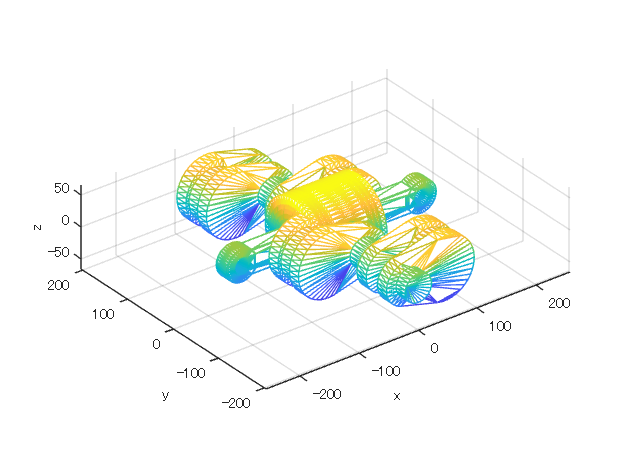

figure;
hold on;
for istl = 1:length(model.stl)
    trimesh(model.stl(istl).tri);
end
xlabel('x'); ylabel('y'); zlabel('z'); grid on; axis equal; view(3);

パッチ数を減らす．

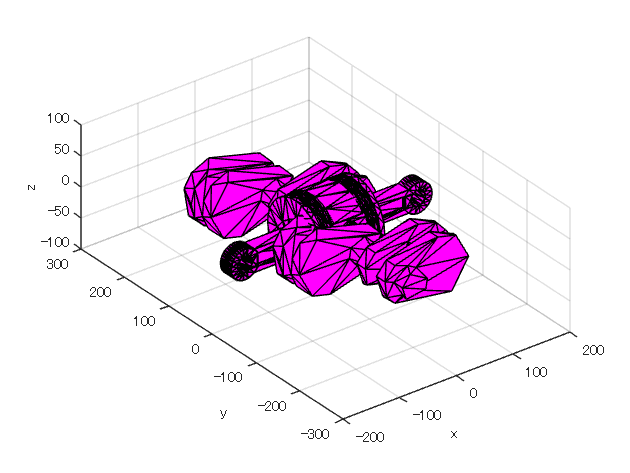


Reduce_Rate = 0.2; % 何倍にするか

figure;
hold on;
for istl = 1:length(model.stl)
    p = model.stl(istl).tri.Points;
    c = model.stl(istl).tri.ConnectivityList;
    pat = patch('Faces', c, 'Vertices', p, FaceColor='magenta');
    reducepatch(pat, Reduce_Rate);
    model.stl(istl).reduced_tri = triangulation(pat.Faces, pat.Vertices);
end
xlim([-300, 300]); ylim([-300, 300]); zlim([-100, 100]); xlabel('x'); ylabel('y'); zlabel('z'); grid on; axis equal; view(3);

アニメーションを適用し， NFRAME 数でサンプリング

interval = floor(length(model.tout)/NFRAME);
iframe = 0;
for t = 1:interval:length(model.tout)
    iframe = iframe + 1;
    for istl = 1:length(model.stl)
        p = model.stl(istl).reduced_tri.Points;
        p = (model.stl(istl).rotation(:,:,t) * p.').' + model.stl(istl).translation(:,:,t);
        model.stl(istl).p(:,:,iframe) = p;
    end
end


表示

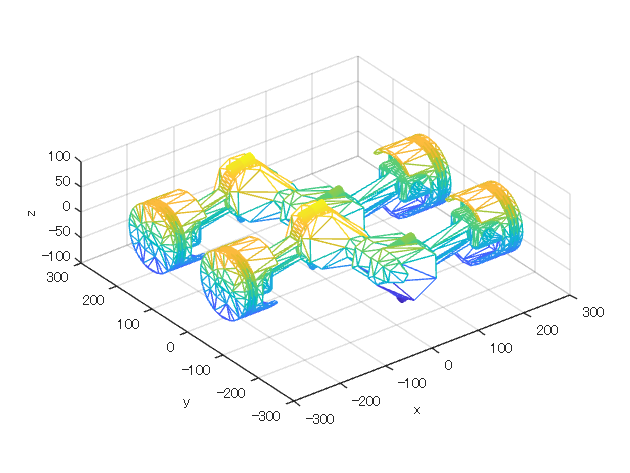

figure;
for iframe = 1:NFRAME
    clf;
    hold on;
    for istl = 1:length(model.stl)
        p = model.stl(istl).p;
        trimesh(model.stl(istl).reduced_tri.ConnectivityList, p(:,1,iframe), p(:,2,iframe), p(:,3,iframe));
    end
    
    xlim([-300, 300]); ylim([-300, 300]); zlim([-100, 100]); xlabel('x'); ylabel('y'); zlabel('z'); grid on; axis equal; view(3);
    pause(0.1);
end

ラドン変換


J = 2; % 緯度方向の視点数
K = 4; % 経度方向の視点数
Diameter = 900; % ラドン変換の直径

for istl = 1:length(model.stl)
    model.stl(istl).radon.J = J;
    model.stl(istl).radon.K = K;
    model.stl(istl).radon.Diameter = Diameter;
    model.stl(istl).radon.frame = repmat( ...
        struct('sph_volume', zeros(J*K, Diameter)), ...
        NFRAME, 1 ...
        );
    model.stl(istl).radon.processTime = 0;
end

az_vec = 0:2*pi/K:2*pi-0.0001;
syms x;
el_vec = asin(double(vpasolve(legendreP(J, x))));
el_vec = el_vec(end:-1:1);
[AZ, EL] = meshgrid(az_vec, el_vec);
az = AZ(:);
el = EL(:);

model_stl = model.stl;
parfor istl = 1:length(model.stl)
    tic;
    el_local = el;
    az_local = az;
    stl = model_stl(istl);
    for iframe = 1:NFRAME
        p = stl.p(:,:,iframe);
        c = stl.reduced_tri.ConnectivityList;
        sph_volume = zeros([J*K, Diameter]);
        for isp = 1:J*K

            %Y軸の回転行列
            rotateY = [
                cos(el_local(isp)), 0, sin(el_local(isp));
                0, 1, 0;
                -sin(el_local(isp)), 0, cos(el_local(isp))
                ];

            %Z軸の回転行列
            rotateZ = [
                cos(-az_local(isp)), -sin(-az_local(isp)), 0;

                sin(-az_local(isp)), cos(-az_local(isp)), 0;
                0, 0, 1
                ];
            rotated_p = (rotateY*rotateZ*p.').' + Diameter/2;

            %外積計算
            p1 = rotated_p(c(:,1),:);
            p2 = rotated_p(c(:,2),:);
            p3 = rotated_p(c(:,3),:);
            a = p2 - p1;
            b = p3 - p1;
            cross_ab = [a(:,2).*b(:,3) - b(:,2).*a(:,3), a(:,3).*b(:,1) - b(:,3).*a(:,1), a(:,1).*b(:,2) - b(:,1).*a(:,2)];
            pos_neg_zero = +(cross_ab(:,3) > 0.0001) - (cross_ab(:,3) < 0);

            nc = sum(pos_neg_zero ~= 0);

            p1 = p1(pos_neg_zero ~= 0,:);
            p2 = p2(pos_neg_zero ~= 0,:);
            p3 = p3(pos_neg_zero ~= 0,:);

            p1 = p1.';
            p2 = p2.';
            p3 = p3.';

            p123_x = [
                p1(1,:);
                p2(1,:);
                p3(1,:)
                ];
            [sorted_p123_x, ipx] = sort(p123_x, 1);
            column_increment = repmat(0:3:3*(size(ipx,2)-1), [3,1]);
            vec_ipx = ipx(:) + column_increment(:);

            p123_y = [
                p1(2,:);
                p2(2,:);
                p3(2,:)
                ];
            vec_sorted_p123_y = p123_y(vec_ipx);
            sorted_p123_y = reshape(vec_sorted_p123_y, size(p123_y));
            p123_z = [
                p1(3,:);
                p2(3,:);
                p3(3,:)
                ];
            vec_sorted_p123_z = p123_z(vec_ipx);
            sorted_p123_z = reshape(vec_sorted_p123_z, size(p123_z));
            P_xmin = [sorted_p123_x(1,:).', sorted_p123_y(1,:).', sorted_p123_z(1,:).'];
            P_xmid = [sorted_p123_x(2,:).', sorted_p123_y(2,:).', sorted_p123_z(2,:).'];
            P_xmax = [sorted_p123_x(3,:).', sorted_p123_y(3,:).', sorted_p123_z(3,:).'];

            Pos_neg = pos_neg_zero(pos_neg_zero ~= 0,:);

            volume = zeros(1, Diameter);

            %パッチごとにみていく
            for ic = 1:nc
                pos_neg = Pos_neg(ic);
                % if pos_neg == 0
                %     continue;
                % end

                p_xmin = P_xmin(ic,:);
                p_xmid = P_xmid(ic,:);
                p_xmax = P_xmax(ic,:);


                old_volume = 0;
                slice_x = (floor(p_xmin(1) + 1):ceil(p_xmid(1) - 1))';
                slice_x_to_idx = int32(slice_x - 1);
                if ~isempty(slice_x)
                    p1 = p_xmin; p2 = p_xmid;
                    qy = (p2(2)-p1(2))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(2);
                    qz = (p2(3)-p1(3))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(3);
                    q_min_mid = [slice_x, qy, qz];
                    p2 = p_xmax;
                    qy = (p2(2)-p1(2))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(2);
                    qz = (p2(3)-p1(3))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(3);
                    q_min_max = [slice_x, qy, qz];
                    a = q_min_mid - p_xmin;
                    b = q_min_max - p_xmin;
                    area = 0.5*abs(a(:,1).*b(:,2) - b(:,1).*a(:,2));
                    h = (p_xmin(3) + q_min_mid(:,3) + q_min_max(:,3))/3;
                    cur_volume =  area .* h;
                    cur_volume = cur_volume';
                    volume(slice_x_to_idx) = volume(slice_x_to_idx) ...
                        + pos_neg*(cur_volume - [0, cur_volume(1:end-1)]);
                    assert(sum(isnan(volume)) == 0);
                    old_volume = cur_volume(end);
                end


                slice_x = p_xmid(1);
                slice_x_to_idx = floor(p_xmid(1));
                p1 = p_xmin; p2 = p_xmax;
                if slice_x ~= p1(1)
                    qy = (p2(2)-p1(2))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(2);
                    qz = (p2(3)-p1(3))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(3);
                    q_min_max = [slice_x, qy, qz];
                    cur_volume = polyarea([p_xmin(1), p_xmid(1), q_min_max(1)], [p_xmin(2), p_xmid(2), q_min_max(2)]) * (p_xmin(3) + p_xmid(3) + q_min_max(3))/3;
                    volume(slice_x_to_idx) = volume(slice_x_to_idx) + pos_neg*(cur_volume - old_volume);
                end

                old_volume = 0;
                slice_x = (ceil(p_xmax(1)-1):-1:floor(p_xmid(1) + 1))';
                slice_x_to_idx = int32(slice_x);
                if ~isempty(slice_x)
                    p1 = p_xmax; p2 = p_xmid;
                    qy = (p2(2)-p1(2))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(2);
                    qz = (p2(3)-p1(3))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(3);
                    q_mid_max = [slice_x, qy, qz];
                    p2 = p_xmin;
                    qy = (p2(2)-p1(2))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(2);
                    qz = (p2(3)-p1(3))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(3);
                    q_min_max = [slice_x, qy, qz];
                    a = q_mid_max - p_xmax;
                    b = q_min_max - p_xmax;
                    area = 0.5*abs(a(:,1).*b(:,2) - b(:,1).*a(:,2));
                    h = (p_xmax(3) + q_mid_max(:,3) + q_min_max(:,3))/3;
                    cur_volume =  area .* h;
                    cur_volume = cur_volume';
                    volume(slice_x_to_idx) = volume(slice_x_to_idx) ...
                        + pos_neg*(cur_volume - [0, cur_volume(1:end-1)]);
                    assert(sum(isnan(volume)) == 0);
                    old_volume = cur_volume(end);
                end

                slice_x = p_xmid(1);
                slice_x_to_idx = floor(slice_x);
                p1 = p_xmax; p2 = p_xmin;
                if slice_x ~= p1(1)
                    qy = (p2(2)-p1(2))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(2);
                    qz = (p2(3)-p1(3))/(p2(1)-p1(1))*(slice_x-p1(1)) + p1(3);
                    q_min_max = [slice_x, qy, qz];
                    cur_volume = polyarea([p_xmid(1), q_min_max(1), p_xmax(1)], [p_xmid(2), q_min_max(2), p_xmax(2)]) * (p_xmid(3) + q_min_max(3) + p_xmax(3))/3;
                    volume(slice_x_to_idx) = volume(slice_x_to_idx) + pos_neg*(cur_volume - old_volume);
                end
            end
            sph_volume(isp, :) = volume;
        end
        stl.radon.frame(iframe).sph_volume = sph_volume;
    end
    stl.radon.processTime = toc;
    model_stl(istl) = stl;
end
model.stl = model_stl;


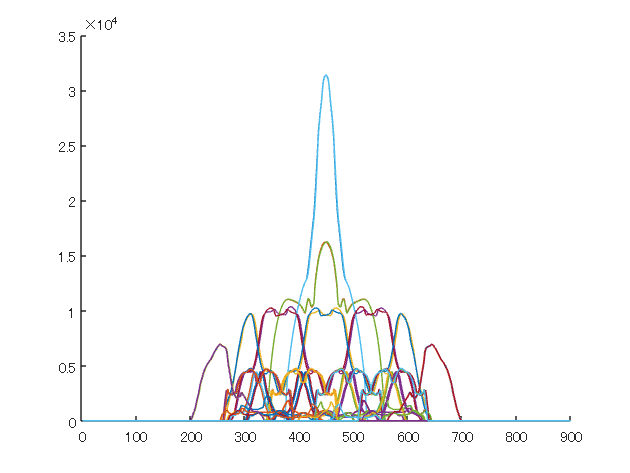


figure;
for iframe = 1:NFRAME
    clf;
    hold on;
    for istl = 1:length(model.stl)
        for isp = 1:J*K
            plot(model.stl(istl).radon.frame(iframe).sph_volume(isp,:));
        end
    end
    pause(0.5);
end